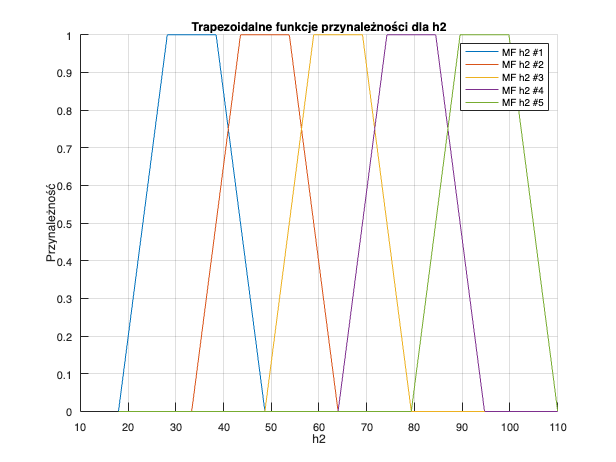

clear all;
% trapez
% 
% 
% Parametry testowe
N = 5; % Liczba funkcji przynależności
[mf_h1, mf_h2] = generate_trapezoidal_mf_functions(N); % Wywołanie istniejącej funkcji


% Zakresy dla zmiennych h2 i h1
h2_pp_min = 18;
h2_pp_max = 110;
h1_pp_min = mf_h1(1).params(1); % Początek zakresu h1
h1_pp_max = mf_h1(end).params(4); % Koniec zakresu h1

% Dyskretyzacja zakresów dla wykresu
h2_range = linspace(h2_pp_min, h2_pp_max, 1000);
h1_range = linspace(h1_pp_min, h1_pp_max, 1000);

% Wyświetlanie funkcji przynależności dla h2
figure;
hold on;
grid on;
title('Trapezoidalne funkcje przynależności dla h2');
xlabel('h2');
ylabel('Przynależność');
for i = 1:N
    % Obliczanie wartości przynależności
    mf_values_h2 = evalmf( mf_h2(i),h2_range);
    plot(h2_range, mf_values_h2, 'DisplayName', sprintf('MF h2 #%d', i));
end
legend show;

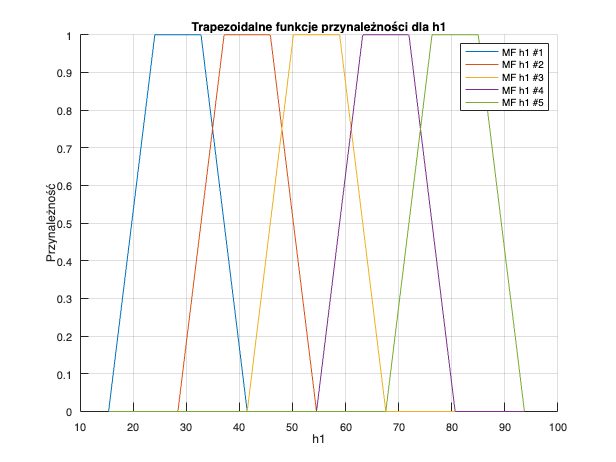


% Wyświetlanie funkcji przynależności dla h1
figure;
hold on;
grid on;
title('Trapezoidalne funkcje przynależności dla h1');
xlabel('h1');
ylabel('Przynależność');
for i = 1:N
    % Obliczanie wartości przynależności
    mf_values_h1 = evalmf( mf_h1(i),h1_range);
    plot(h1_range, mf_values_h1, 'DisplayName', sprintf('MF h1 #%d', i));
end
legend show;

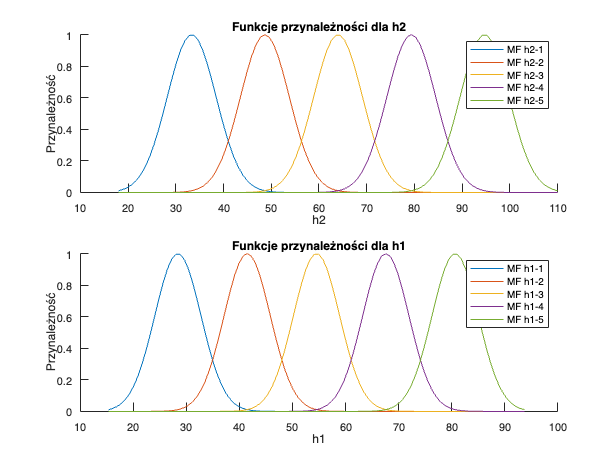

Funkcje przynależności dla h2:


  5×1 fismf array with properties:

    Type
    Parameters
    Name

  Details:
         Name      Type          Parameters   
         ____    _________    ________________

    1    "mf"    "gaussmf"    5.1111    33.333
    2    "mf"    "gaussmf"    5.1111    48.667
    3    "mf"    "gaussmf"    5.1111        64
    4    "mf"    "gaussmf"    5.1111    79.333
    5    "mf"    "gaussmf"    5.1111    94.667



Funkcje przynależności dla h1:


  5×1 fismf array with properties:

    Type
    Parameters
    Name

  Details:
         Name      Type         Parameters   
         ____    _________    _______________

    1    "mf"    "gaussmf"    4.355    28.402
    2    "mf"    "gaussmf"    4.355    41.467
    3    "mf"    "gaussmf"    4.355    54.533
    4    "mf"    "gaussmf"    4.355    67.598
    5    "mf"    "gaussmf"    4.355    80.663



% Gaus
% 
% 
clear all;
% Parametry testowe
N = 5; % liczba funkcji przynależności

% Generowanie funkcji przynależności
[mf_h1, mf_h2] = generate_gaussian_mf_functions(N);

% Zakresy dla wykresów
h2_pp_min = 18;
h2_pp_max = 110;

% Tworzenie punktów do oceny funkcji przynależności
h2_values = linspace(h2_pp_min, h2_pp_max, 100);
h1 = @(h2) h2 * (12 / 13)^2; % Funkcja przekształcająca h2 na h1
h1_values = h1(h2_values);

% Wykresy funkcji przynależności
figure;

% Wykres dla h2
subplot(2, 1, 1);
hold on;
for i = 1:N
    plot(h2_values, evalmf( mf_h2(i),h2_values), 'DisplayName', sprintf('MF h2-%d', i));
end
hold off;
title('Funkcje przynależności dla h2');
xlabel('h2');
ylabel('Przynależność');
legend;

% Wykres dla h1
subplot(2, 1, 2);
hold on;
for i = 1:N
    plot(h1_values, evalmf( mf_h1(i),h1_values), 'DisplayName', sprintf('MF h1-%d', i));
end
hold off;
title('Funkcje przynależności dla h1');
xlabel('h1');
ylabel('Przynależność');
legend;

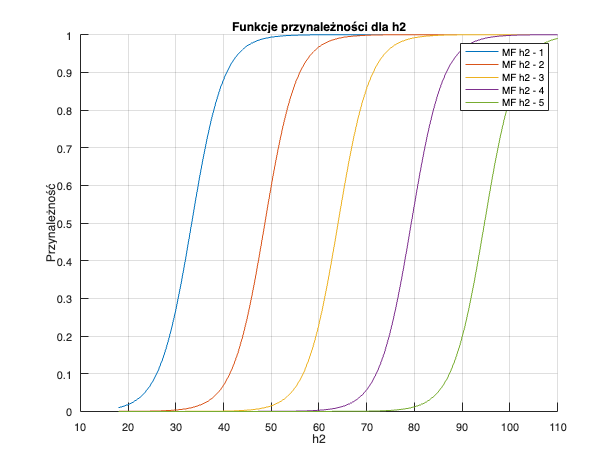

%Sigmodalna

clear all;
% Skrypt do testowania funkcji generate_sigmoid_mf_functions

% Liczba funkcji przynależności do wygenerowania
N = 5;

% Wywołanie funkcji generującej funkcje przynależności
[mf_h1, mf_h2] = generate_sigmoid_mf_functions(N);

% Przygotowanie wektora wartości, na którym będziemy testować funkcje przynależności
h2_values = linspace(18, 110, 100);  % Wartości h2 od 18 do 110
h1_values = arrayfun(@(h2) h2 * (12 / 13)^2, h2_values);  % Obliczanie odpowiadających h1 dla h2

% Rysowanie funkcji przynależności h2
figure;
hold on;
title('Funkcje przynależności dla h2');
xlabel('h2');
ylabel('Przynależność');
grid on;
for i = 1:N
    % Obliczanie wartości funkcji sigmoidalnej dla h2
    h2_mf_values = arrayfun(@(h2) evalmf(mf_h2(i), h2), h2_values);
    plot(h2_values, h2_mf_values, 'DisplayName', ['MF h2 - ' num2str(i)]);
end
legend;
hold off;

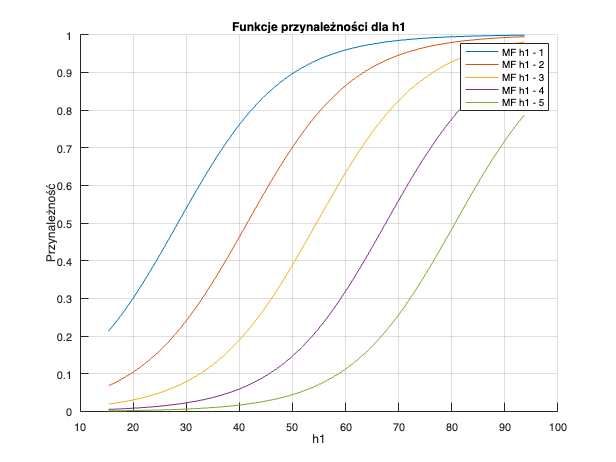


% Rysowanie funkcji przynależności h1
figure;
hold on;
title('Funkcje przynależności dla h1');
xlabel('h1');
ylabel('Przynależność');
grid on;
for i = 1:N
    % Obliczanie wartości funkcji sigmoidalnej dla h1
    h1_mf_values = arrayfun(@(h1) evalmf(mf_h1(i), h1), h1_values);
    plot(h1_values, h1_mf_values, 'DisplayName', ['MF h1 - ' num2str(i)]);
end
legend;
hold off;